Readme

 % ZHANG Jianchao 2023/4/25 

% Revised by Jun Suzuki 2023/4/28

### **Introduction**: 

In quantum estimation theory, the classical Fisher information matrix (CFIM) is of vital importance in the problem of finding the best measurement which gives the most information about parameters encoded in a family of quantum states. The main objective of this code, QestOpt, is to obtain an optimal measurement and the minimum value of the trace of the inverse of the CFIM for a given quantum state numerically. This problem can be formulated as a convex optimization problem, and we implement a code based on the standard steepest descent method to find the best gradient direction. Hence, optimization is efficient and numerically accurate. 

### **Problem setting**: 

Suppose we have a family of quantum states which is parametrized by n parameters as $\rho_\theta$ with $\theta=(\theta_1,\theta_2,\cdots,\theta_n)$. We aim at finding the true parameter value $\theta_0$ by performing a suitable measurement. Here the measurement is mathematically described by a positive operator-valued measure (POVM), which is denoted by $\Pi =\left\lbrace \Pi_1 ,\Pi_2 ,\cdots ,\Pi_K \right\rbrace$ ($K$outcomes). By performing $\Pi$ on $\rho_\theta$, we have a probability distribution $p_{\theta } \left(k\right)=\textrm{Tr}\;\rho_{\theta } \Pi_k$. This defines the CFIM $J_{\theta } \left(\Pi \right)$ whose ij component is defined by 


$$J_{\theta,ij}(\Pi)=
\sum_{k=1}^K \frac{Tr(\partial_i\rho_\theta \Pi_k)Tr(\partial_j\rho_\theta \Pi_k)}{Tr(\rho_\theta \Pi_k)}$$


From this definition, we see that it is sufficient to specify a state $\rho_{\theta_0 }$ and its derivatives in each direction $\rho_{\theta_0 ,i} \;$in order to calculate the CFIM, where $\rho_{\theta_0,i} = \left.\frac{\partial \rho_
\theta}{\partial \theta_i}\right|_{\theta=\theta_0}$ . This is called the local settings, which will be explained later in this part. 

We are interested in minimizing the inverse of the CFIM, since it gives the minimum variance of an unbiased estimator. This is accomplished by calculating the minimal value of trace of inverse of the CFIM $ {\rm Tr} [ (J_\theta(\Pi))^{-1}]$. (This is called the A-optimal design. ref1).

To find the optimal POVM among all possible POVMs, we need first solve a restricted class of optimization, where the number of POVM elements is given as $K$. The POVM is the a set of matrices where each matrix is semidefinite positive and the summation of matrices is identity. The optimization problem is written as follows. 


$$\min_{\Pi} {\rm Tr} [ (J_\theta(\Pi))^{-1}]\\
s.t. \forall k,\ \Pi_k\geq0,\ and \sum_{k=1}^K \Pi_k=I$$


$J_\theta$: Fisher information matrix, a function of the state and measurement.

$\Pi$: POVM (positive operator-valued measurement)

$\rho_\theta$: quantum state, a function of parameters $\theta$.

This means, for a given K, we have a space of POVMs. After finding an optimal POVM for each $K$, we compare different $K$s to obtain the best choice for $K$. Therefore, we can find the best POVM in the space of all possible POVMs. 

In the following, we will drop the parameter $\theta$ when we fix it at some point. In this case, we need to specify a state $\rho$ and its derivatives $\rho_i =\partial_i \rho$ ($i=1,2,\cdots ,n$).

Here are additional comments on the local setting. 

The local setting is a special case of estimation problems. In the real problem, the parameter theta is unknown. The POVM relates to the design of the experiment. What we want is to find the relatively best POVM that could extract the most information about theta. However, this is extremely complicated if we have no prior information about theta. 

The local settings means for each given true parameter theta, we find the optimal POVM that maximizes the Classical Fisher Information. Also, this means the locally optimal POVM depends on theta.

Under local setting, our algorithm has the following three guiding functions

- In some special cases, this locally optimal POVM is global.

- In design of experiment, this method gives the help in two stage estimation or sequential design estimation.

- This method suggests how we shrink the sample size.

#### Quick start with  a minimum necessary input. 

Firstly, let us see a quick start. With a given state rho and derivatives of state drho{j} (j=1,2,...n), we find the optimal POVM. As a simple example (two-parameter qubit with three POVM outcomes), this is executed as follows. 

%rho and drho is given 
rho=0.5*eye(2);

drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];

[povm,ob]=Qest([],rho,drho,'k',3);  %Find the optical POVM set with 3 elements.

Stop at iteration : 52 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 


ob-4

ans = 1.1404e-10

From the output, we can see the algorithm stops at 42 iterations when variation is small. And the corresponding objective function value is 4. 

#### Options. 

There are many options in the input. In order to describe the function of this algorithm clearly, the explanation of each parameter is stated in a table.

**Table of options:**

ParameterName = ["k";"klim";"tensor";"povm";"seed";"Conjugate";"weight";"check"];%
Explanation = ["The number of POVM elements";
    "get all results among a set of k";
    "Control tensor product";
    "Use specified initial POVM or not";
    "random seed, if empty, means random each time";
    "Conjugate gradient. 1 means use conjugate gradient.";
    "Weight matrix setting";
    "Show the validation check"];%
InputType = ["int";"list of int";"int";"int";"cell of matrix";"boolean";"matrix";"boolean"];%

table(ParameterName,Explanation,InputType)

ans = 8×3 table
    ParameterName                         Explanation                            InputType    
    _____________    _____________________________________________________    ________________

     "k"             "The number of POVM elements"                            "int"           
     "klim"          "get all results among a set of k"                       "list of int"   
     "tensor"        "Control tensor product"                                 "int"           
     "povm"          "Use specified initial POVM or not"                      "int"           
     "seed"          "random seed, if empty, means random each time"          "cell of matrix"
     "Conjugate"     "Conjugate gradient. 1 means use conjugate gradient."    "boolean"       
     "weight"        "Weight matrix setting"                                  "matrix"        
     "check"         "Show

To specifically explain the parameters, we use several examples below. They are designed to present the way to use different inputs. This table is easy to see a certain parameter is described by which example. 

ParameterName = ["k";"klim";"tensor";"povm";"seed";"Conjugate";"weight";"check"];%
ExampleSerial = ["1,2";
    "3";
    "4";
    "5";
    "6";
    "7"; 
    "8";
    "N/A"];%
table(ParameterName,ExampleSerial)

ans = 8×2 table
    ParameterName    ExampleSerial
    _____________    _____________

     "k"                 "1,2"    
     "klim"              "3"      
     "tensor"            "4"      
     "povm"              "5"      
     "seed"              "6"      
     "Conjugate"         "7"      
     "weight"            "8"      
     "check"             "N/A"    


### Example 1: qubit case 

State and derivatives; $\rho=\frac{1}{2}
\pmatrix{1 & 0 \cr 0 &1}$, $\partial_1\rho=\frac{1}{2}\pmatrix{0 & 1 \cr 1 &0}$，$\partial_2\rho=\frac{1}{2}\pmatrix{0 & -i \cr i &0}$

This is a two-parameter qubit model and the parameter is set so that the state is the completely mixed-state. 

number of parameter(N)=2,  N equals to the dimension of derivative of rho

number of POVM elements(K)=3.

Find the POVM set gives the minimal of the objective function.

Qest(rho,drho,'k',3)

%Set rho and drho 
rho=0.5*eye(2);

drho=cell(1,2); %the size for derivative of rho
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];
d=2;    %dimension of hilbert space, e.g. qubit means d=2;
n=2;    % number of parameters 
setting=[d,n];
%we recommend to use setting, but if you are not sure what is
%setting, use setting=[];
%setting=[];


[povm,ob]=Qest(setting,rho,drho,'k',3);  %Find the optical POVM set with 3 elements.

Stop at iteration : 52 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 


celldisp(povm);

 
povm{1} =
 
   0.3333 + 0.0000i  -0.0362 + 0.3314i
  -0.0362 - 0.3314i   0.3333 + 0.0000i

 
 
povm{2} =
 
   0.3333 + 0.0000i   0.3051 - 0.1343i
   0.3051 + 0.1343i   0.3333 + 0.0000i

 
 
povm{3} =
 
   0.3333 + 0.0000i  -0.2689 - 0.1970i
  -0.2689 + 0.1970i   0.3333 + 0.0000i

 


### Example 2: Qutrit case

The next example is a qutrit model, which means the dimension of a hilbert space is 3. The state is a normalized identity (the completely mixed state) and the derivative is the same as the previous one. Additionally, the seed is used and set as 1. It is easy to check that this example will provides the same POVM on each repetition.

Besides that, the input argument 'check' is set as 1. This means the validation check of parameters is shown in consoles. Otherwise it is hidden and only visible when a warning or wrong occurs.

% qutrit case with d=3, n=2
rho=eye(3)/3;

drho=cell(1,2);
drho{1}=[0   1/2 0;
         1/2 0   0;
         0   0   0];
drho{2}=[0      -1/2*1i  0;
         1/2*1i 0        0;
         0      0        0];
d=3;    %dimension of hilbert space, e.g. qubit means d=2;
n=2;    % number of parameters 
setting=[d,n];
%we recommend to use setting, but if you are not sure what is
%setting, use setting=[];
%setting=[];

%the seed means we set the seed 1, or we have no fixed seed

[povm,ob]=Qest(setting,rho,drho,'k',3,'seed',1,'check',1);  %Find the optical POVM set with 3 elements.

check dimension of hilbert space
correct
check number of parameters
correct
check n<=d^2-1
correct
check rho is positive definite
correct
check trace of rho is 1
correct
check independency of drho
correct
check trace of drho
correct
correct
check K number of POVM elements is valid
correct
Stop at iteration :168 when delta<1e-10 
Objective function: Trace of inverse of FI :  3.3941719 


celldisp(povm);

 
povm{1} =
 
   0.3139 + 0.0000i   0.1843 - 0.2541i   0.0000 + 0.0000i
   0.1843 + 0.2541i   0.3139 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i

 
 
povm{2} =
 
   0.3139 + 0.0000i   0.1880 + 0.2513i  -0.0000 - 0.0000i
   0.1880 - 0.2513i   0.3139 + 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i

 
 
povm{3} =
 
   0.3723 + 0.0000i  -0.3723 + 0.0028i  -0.0000 + 0.0000i
  -0.3723 - 0.0028i   0.3723 + 0.0000i   0.0000 - 0.0000i
  -0.0000 - 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i

 


Explanation of each checkment.

`check dimension of Hilbert space `

`- the dimension is the same as setting.`

`check number of parameters `

`- the number is the same as setting.`

`check n<=d^2-1`

`- less than the greatest number of parameters.`

`check rho is positive definite`

`- rho should be positive definite`

`check trace of rho is 1`

`- trace of rho should be 1.`

`check independency of drho`

`- drho should be linear independent`

`check K number of POVM elements is valid`

`- number of POVM elements has constraints.`

### Example 3: Klim

Find the best POVM within a set of possible POVM outcomes ${\cal K}=\{K_1,K_2,\cdots,K\}$.

This example is provided for the situation that we do not know the appropriate number of POVM elements. It is sufficient to test in a set of numbers and discover the least objective function. If all the numbers in the set produce approximately the same result, we can select the POVM with the minimum number of elements we need.

The following example is when we look for the best POVM with 3, 5, and 7 outcomes. 

Stop at iteration : 51 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 50 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 47 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 


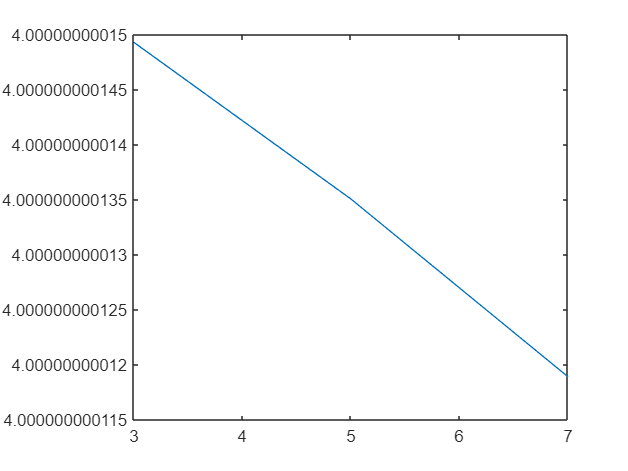

%Set rho and drho 
rho=0.5*eye(2);

drho=cell(1,2);
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];

setting=[];

[povm,ob]=Qest(setting,rho,drho,'klim',[3 5 7]); %Find the optimal POVM set for K=3:10.

celldisp(povm{1}); % here povm{1} is the povm set for K=3. 

 
ans{1} =
 
   0.3333 + 0.0000i   0.0231 + 0.3325i
   0.0231 - 0.3325i   0.3333 + 0.0000i

 
 
ans{2} =
 
   0.3333 + 0.0000i   0.2764 - 0.1863i
   0.2764 + 0.1863i   0.3333 + 0.0000i

 
 
ans{3} =
 
   0.3333 + 0.0000i  -0.2995 - 0.1462i
  -0.2995 + 0.1462i   0.3333 + 0.0000i

 


### Example 4: two qubit model

The i.i.d. extension of a multi-parameter model is of great importance for quantum metrology. This is accomplished by using the option called 'tensor'. 

As an example, the same qubit model (Example 1) is considered. This model is defined by the M tensor product of the single copy model. The state in this example is $\rho^{\otimes M}$. This M-copies model is considered to simultaneously estimate the parameters in multiple qubit. For simplicity we set $M=2$ (two copies). 

%Set rho and drho 
rho=0.5*eye(2)+[0   1/4;
         1/4 0];

drho=cell(1,2);
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];

setting=[2,2];
M=2; % M is the number of tensor product

[povm,ob]=Qest(setting,rho,drho,'k',3,'tensor',M); 

Stop at iteration :937 when delta<1e-10 
Objective function: Trace of inverse of FI :  1.4055753 


celldisp(povm);

 
povm{1} =
 
   0.2748 + 0.0000i  -0.2488 - 0.0002i  -0.2488 - 0.0002i   0.2748 + 0.0004i
  -0.2488 + 0.0002i   0.7252 + 0.0000i  -0.2748 - 0.0000i  -0.2488 - 0.0002i
  -0.2488 + 0.0002i  -0.2748 + 0.0000i   0.7252 + 0.0000i  -0.2488 - 0.0002i
   0.2748 - 0.0004i  -0.2488 + 0.0002i  -0.2488 + 0.0002i   0.2748 + 0.0000i

 
 
povm{2} =
 
   0.3627 + 0.0000i   0.1245 - 0.1852i   0.1245 - 0.1852i  -0.1371 - 0.3358i
   0.1245 + 0.1852i   0.1373 + 0.0000i   0.1373 - 0.0000i   0.1245 - 0.1852i
   0.1245 + 0.1852i   0.1373 + 0.0000i   0.1373 + 0.0000i   0.1245 - 0.1852i
  -0.1371 + 0.3358i   0.1245 + 0.1852i   0.1245 + 0.1852i   0.3627 + 0.0000i

 
 
povm{3} =
 
   0.3625 + 0.0000i   0.1243 + 0.1854i   0.1243 + 0.1854i  -0.1378 + 0.3353i
   0.1243 - 0.1854i   0.1375 + 0.0000i   0.1375 + 0.0000i   0.1243 + 0.1854i
   0.1243 - 0.1854i   0.1375 - 0.0000i   0.1375 + 0.0000i   0.1243 + 0.1854i
  -0.1378 - 0.3353i   0.1243 - 0.1854i   0.1243 - 0.1854i   0.3625 + 0.0000i

 


### Example 5: Use known povm as initialization.

In QestOpt, the default setting of an initial POVM is randomly chosen. This is the reason that if we do not set the seed, the result of each run will be different. We can set a specific value of the seed (See the next example.) for reproducing the same result. Alternatively, we can start with a given initial POVM. This option is useful to test if some special POVM is optimal or not. Also we can start the algorithm with a specific POVM we already got to save the computing time. 

Here is an example with three outcomes povm{k}. Note that this POVM is not normalized (the summation is not equal to the identity matrix.), however the code will automatically normalize it as long as each element is semi-definite positive.  

%Set rho and drho 
rho=0.5*eye(2);

drho=cell(1,2);
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];
d=2;    %dimension of hilbert space, e.g. qubit means d=2;
n=2;    % number of parameters 
setting=[d,n];
%setting=[]; it's alternative arguments.
povm=cell(1,3);
povm{1}=eye(2)+0.5*[0   1; % known initialization povm
                1  0];
povm{2}=eye(2)+0.5*[0   -1i;
                1i  0];
povm{3}=eye(2)+0.5*[1  0;
                0  -1];

[povm,ob]=Qest(setting,rho,drho,'povm',povm,'seed',1);  %Find the optical POVM set with 3 elements.

Stop at iteration : 53 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 


celldisp(povm);

 
povm{1} =
 
   0.3333 + 0.0000i   0.3220 + 0.0863i
   0.3220 - 0.0863i   0.3333 + 0.0000i

 
 
povm{2} =
 
   0.3333 + 0.0000i  -0.0863 - 0.3220i
  -0.0863 + 0.3220i   0.3333 + 0.0000i

 
 
povm{3} =
 
   0.3333 + 0.0000i  -0.2357 + 0.2357i
  -0.2357 - 0.2357i   0.3333 + 0.0000i

 


### Example 6 Multiple seeds

The main issue upon finding the optimal POVM is that the POVM space is large, and the optimization algorithm will stop at local minima. This is a well-known and common problem in a practical optimization problem. One way to avoid local minima is to run the algorithm from different initial POVMs. We may try different seeds many times to see the best result. 

Here we provide two methods to implement this. The first one is that we want to find the best one over many seeds.

%Multiple seeds case 1
rho=0.5*eye(2);

drho=cell(1,2);
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];

setting=[2,2];

seedset=[1 3 5]; % we try to get the best one from this set of seeds

minob=1e+10;
for i=seedset
    [povm,ob]=Qest(setting,rho,drho,'k',3,'seed',i);  
    if ob<minob % find better one
        minob=ob;
        currentpovm=povm;
    end
end

Stop at iteration : 55 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 45 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 55 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 


povm=currentpovm;
disp(minob);

    4.0000



celldisp(povm);

 
povm{1} =
 
   0.3333 + 0.0000i   0.0950 - 0.3195i
   0.0950 + 0.3195i   0.3333 + 0.0000i

 
 
povm{2} =
 
   0.3333 + 0.0000i  -0.3242 + 0.0775i
  -0.3242 - 0.0775i   0.3333 + 0.0000i

 
 
povm{3} =
 
   0.3333 + 0.0000i   0.2292 + 0.2420i
   0.2292 - 0.2420i   0.3333 + 0.0000i

 


The second one is the case where we want to figure out how this algorithm is influenced by different seeds. In order to do this, we set a method to output a set of objective functions. If these values have small variance means no much impact by the setting of seeds.

%Multiple seeds case 2
rho=0.5*eye(2);

drho=cell(1,2);
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];

setting=[2,2];

seedset=1:20; % we try to get the set of all objective function
oblist=zeros(1,20);
k=3;
povmlist=cell(3,20); %povmlist is a cell evolving all povm, 
% e.g. povmlist(:,1) is a cell containing the povm when seed is 1

for i=seedset
    [povm,ob]=Qest(setting,rho,drho,'k',3,'seed',i);  
    oblist(i)=ob;
    povmlist(:,i)=povm;
end

Stop at iteration : 55 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 55 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 45 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 52 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 55 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 51 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 54 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 57 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 55 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 48 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 
Stop at iteration : 

disp(oblist);

  Columns 1 through 14

    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000

  Columns 15 through 20

    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000



celldisp(povmlist(:,5)); %have a look at 5th povm

 
ans{1} =
 
   0.3333 + 0.0000i   0.0950 - 0.3195i
   0.0950 + 0.3195i   0.3333 + 0.0000i

 
 
ans{2} =
 
   0.3333 + 0.0000i  -0.3242 + 0.0775i
  -0.3242 - 0.0775i   0.3333 + 0.0000i

 
 
ans{3} =
 
   0.3333 + 0.0000i   0.2292 + 0.2420i
   0.2292 - 0.2420i   0.3333 + 0.0000i

 


disp(var(oblist));

   4.2646e-22



We can see in this case variance of oblist is extremely small. This means that setting a different seed is totally unnecessary in this case. 

### Example 7 Conjugate gradient

There is a known drawback of gradient descent is that in some cases, the gradient descent will be significantly small due to the dimension of space. And it can fluctuate because of the shape of the contour. 

Conjugate gradient (CG) is an extended version of gradient descent. It could handle the above mentioned problem when the gradient is tiny. There is no such thing that CG is strictly better than gradient descent but it is worth trying when we can not find the answer by gradient descent.

The original CG is presented in scalar, here is the version designed for a matrix.

%Conjugate gradient
rho=0.5*eye(2);

drho=cell(1,2);
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];
d=2;    % dimension of hilbert space, e.g. qubit means d=2;
n=2;    % number of parameters 
setting=[d,n];
useCG=1 % 1 means use, 0 means do not use. default does not use

useCG = 1


[povm,ob]=Qest(setting,rho,drho,'k',4,'seed',2,'Conjugate',useCG);  

Stop at iteration :373 when delta<1e-10 
Objective function: Trace of inverse of FI :  4.0000000 


celldisp(povm);

 
povm{1} =
 
   0.3201 + 0.0000i   0.2941 - 0.1263i
   0.2941 + 0.1263i   0.3201 + 0.0000i

 
 
povm{2} =
 
   0.3331 + 0.0000i  -0.0425 + 0.3303i
  -0.0425 - 0.3303i   0.3331 + 0.0000i

 
 
povm{3} =
 
   0.3331 + 0.0000i  -0.2651 - 0.2017i
  -0.2651 + 0.2017i   0.3331 + 0.0000i

 
 
povm{4} =
 
   0.0137 + 0.0000i   0.0135 - 0.0023i
   0.0135 + 0.0023i   0.0137 + 0.0000i

 


### Example 8 Weight Matrix

There are cases we consider to solve the following optimization problem instead.


$$\min_{\Pi} {\rm Tr} [ W (J_\theta(\Pi))^{-1}]\\
s.t. \forall k,\ \Pi_k\geq0,\ and \sum_{k=1}^K \Pi_k=I$$


As compared with the original question, there is an additional weight matrix W. The purpose of plugging in the weight matrix is to change the coordinate system. The gradient will be slightly different as before and has a linear relation with the weight matrix.

Below is an example of using a weight matrix.

% Weight matrix
rho=0.5*eye(2);

W=[1.5 0;
    0  0.5]; % weight matrix
drho=cell(1,2);
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];
d=2;    % dimension of hilbert space, e.g. qubit means d=2;
n=2;    % number of parameters 
setting=[d,n];

[povm,ob]=Qest(setting,rho,drho,'k',3,'seed',1,'weight',W);  

Stop at iteration : 55 when delta<1e-10 
Objective function: Trace of inverse of FI :  3.7320508 


celldisp(povm);

 
povm{1} =
 
   0.3713 + 0.0000i  -0.3523 + 0.1175i
  -0.3523 - 0.1175i   0.3713 + 0.0000i

 
 
povm{2} =
 
   0.2687 + 0.0000i   0.0250 - 0.2675i
   0.0250 + 0.2675i   0.2687 + 0.0000i

 
 
povm{3} =
 
   0.3600 + 0.0000i   0.3272 + 0.1500i
   0.3272 - 0.1500i   0.3600 + 0.0000i

 


We know that in this case the optimal value is given by $({\rm Tr}\sqrt{W})^2$. We can easily find they are equal and the accuracy is up to 10 digits.

trace(sqrt(W))^2

ans = 3.7321

trace(sqrt(W))^2-ob

ans = -1.7616e-10

### **Stopping rules options**

The stopping rule used in this program has two criteria. If one of them is satisfied, the iteration will be stopped. 

- The significantly small variance. 

At each step, the code detects the difference between objective functions. If the gap is smaller than the endurance setted in advance, the iteration step will stop. We need to clarify that the gap is the difference between each steps. This means is does not confirm the difference between the end point and the ture value. The default value is set to ${10}^{-10}$. 

        2. The maximum iterations.

It is possible that we can not find a numerically good answer after many iterations. The maximal number of iterations is setted as we do not want to compute the result endlessly. The default amount is 1000. This number is a little bit small for typical problems.

% Stopping rule
rho=0.5*eye(2);

drho=cell(1,2);
drho{1}=[0   1/2;
         1/2 0];
drho{2}=[0 -1/2*1i;
         1/2*1i 0];
d=2;    % dimension of hilbert space, e.g. qubit means d=2;
n=2;    % number of parameters 
setting=[d,n];

% This two examples are counter examples of setting inappropriate value.
[povm,ob]=Qest(setting,rho,drho,'k',3,'seed',1,'tol',1e-6,'itermax',10);  % The case if itermax is so small

Stop at maximal iteration:  10 
Objective function: Trace of inverse of FI :  4.0774675 


[povm,ob]=Qest(setting,rho,drho,'k',3,'seed',1,'tol',0.1,'itermax',1000); % The case if tol is very large

Stop at iteration :  9 when delta<0.1 
Objective function: Trace of inverse of FI :  4.1196947 


We can see in these two reckless setting, the true value can not be found.

## Other settings and comments:

**Line search:**

The scheme of handling line search, which is the means to find the relatively better step size, is the naive enumerate method. I set a list from 1e-6 to 1e+6 ($\{10^{-6}, 10^{-4}, 10^{-2}, 10^{-1}, 1, 10^{2}, 10^{4},10^{6}\}  $). And at each step, all the candidates in this list will be tested. The one which provides the least objective value will be selected. This method is time inefficient. Based on our empirical test, we can remove some numbers to accelerate the speed of the algorithm. Either we could add the number which we guess would be the best step size to increase the accuracy. This can be done by changing 'alpha' (line 3)  in iteration.m. 

**Precision:**

The accuracy of this algorithm is high in the examples presented. For the given special derivative of state, the qubit, qutrit and up to four i.i.d. model the precision is at least 8 digits. Since many different cases have not been tested, there is not too much to guarantee for other complicated examples.  

**Time cost:**

The cost of time increases linearly with the number of POVM elements (K) but it is exponentially increases with the number of tensor products (M). It is suggested not to test very large numbers M first. The actual execution time, of course, depends on the spec of the hardware. 

**Display of iteration and objective function:**

It is defaulted to show the end of iterations and the result objective function. If the user prefers to make it invisible or change some details, please search fprintf function in Qest.m or 183 line in the same file (The line number may change after some updates).

The version of matlab 2021 has been tested, so please use at least this version. If the older version is compatible, we will update this.